% ----------------- %
% Projet 1 SLAM EKF %
% ----------------- %

clear all; close all;


## Creation de la carte

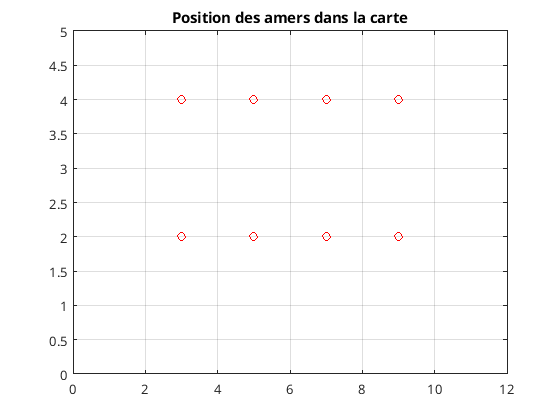

%Distances entre les amers
distXamer = 2;
disYamer = -2;

%Position des amers, vecteur de position des amers :
%    - elements impairs : position en X de l'amer 2*i-1
%    - elements pairs : position en Y de l'amer 2*i
amer=[3 ;4];

for i=2:4
    amer(2*i-1) = amer(2*i-3)+distXamer;
    amer(2*i) = amer(2);
end
for i=5:8
    amer(2*i-1) = amer(2*i-9);
    amer(2*i) = amer(2)+disYamer;
end
%Affichage des amers
figure(1)
plot(amer(1:2:16), amer(2:2:16), 'or')
grid on 
axis([0 12 0 5])
title("Position des amers dans la carte")

## Génération des données réelles

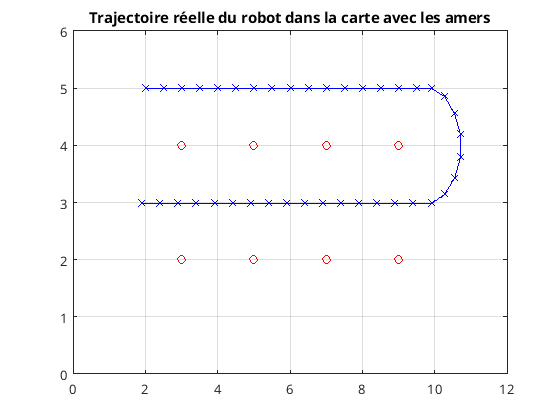

%Nombre d'instants
N1 = 15;
N2 = 8;
N3 = 17;
N = N1+N2+N3;

%Genération de la position du robot 
%Position initiale
Xr(:,1) = [2;5;0];
%Vecteur de commande
for i=1:N1
    U(:,i)=[0.5;0;0];
end
for i=N1+1:N1+N2
    U(:,i)=[0.4;0;-pi/N2];
end
for i=N1+N2+1:N1+N2+N3
    U(:,i)=[0.5;0;0];
end
%Boucle de generation de la trajectoire
for i=2:N
    Xr(:,i)=Xr(:,i-1)+[U(1,i-1)*cos(Xr(3,i-1))-U(2,i-1)*sin(Xr(3,i-1)) ; U(1,i-1)*sin(Xr(3,i-1))+U(2,i-1)*cos(Xr(3,i-1)) ; U(3,i-1)];
end

%Affichage de la trajectoire du robot 
figure(2)
plot(amer(1:2:16), amer(2:2:16), 'or')
hold on
plot(Xr(1,:), Xr(2,:), 'x-b')
axis([0 12 0 6])
grid on
title("Trajectoire réelle du robot dans la carte avec les amers")


%Generation des mesures 
%Pas de mesures a l'etat initial 
z(:,1) = NaN * ones(2*8,1);

%Genrations de mesures pour les instants 2 a N
for k=2:N
    for j=1:8
        z(2*j-1,k) = sqrt((amer(2*j-1)-Xr(1,k))^2+(amer(2*j)-Xr(2,k))^2);
        z(2*j,k) = atan2((amer(2*j)-Xr(2,k)),(amer(2*j-1)-Xr(1,k)))-Xr(3,k);
    end
end

z =        NaN    1.1180    1.0000    1.1180    1.4142    1.8028    2.2361    2.6926    3.1623    3.6401    4.1231    4.6098    5.0990    5.5902    6.0828    6.5765    6.9721    7.3187    7.5734    7.7079    7.7082    7.5743    7.3200    6.9737    6.4794    5.9860    5.4938    5.0032    4.5146    4.0289    3.5471    3.0712    2.6042    2.1522    1.7268    1.3535    1.0872    1.0159    1.1756    1.4940
       NaN   -1.1071   -1.5708   -2.0344   -2.3562   -2.5536   -2.6779   -2.7611   -2.8198   -2.8633   -2.8966   -2.9229   -2.9442   -2.9617   -2.9764   -2.9889   -2.6050   -2.2402   -1.8889   -1.5456    5.0784    5.4218    5.7730    6.1377    6.1265    6.1135    6.0981    6.0797    6.0573    6.0296    5.9942    5.9478    5.8845    5.7942    5.6578    5.4398    5.0892    4.6138    4.1768    3.8848
       NaN    2.6926    2.2361    1.8028    1.4142    1.1180    1.0000    1.1180    1.4142    1.8028    2.2361    2.6926    3.1623    3.6401    4.1231    4.6098    5.0010    5.3372    5.5810    

## Filtrage

## Affichage des données